Project DATA603 - Neural Networks 

close all 
data = load('mnist.mat'); 
imgs_train = data.imgs_train; 
imgs_test = data.imgs_test; 
labels_train = data.labels_train; 
labels_test = data.labels_test 

labels_test = 10000×1 categorical array
     7 
     2 
     1 
     0 
     4 
     1 
     4 
     9 
     5 
     9 
     0 
     6 
     9 
     0 
     1 
     5 
     9 
     7 
     3 
     4 
     9 
     6 
     6 
     5 
     4 
     0 
     7 
     4 
     0 
     1 


[d1, d2, n] = size(imgs_train);
XTrain = zeros(n,d1*d2);
for j = 1:n
aux = imgs_train(:,:,j);
XTrain(j,:) = aux(:)';
end
n1 = n;
[d1, d2, n] = size(imgs_test);
XTest = zeros(n,d1*d2);
for j = 1:n
aux = imgs_test(:,:,j);
XTest(j,:) = aux(:)';
end

[d1,d2,ntrain] = size(imgs_train); 
Xtrain = zeros(d1,d2,1,ntrain); 
for j = 1:ntrain
    Xtrain(:,:,1,j) = imgs_train(:,:,j); 
end
[d1,d2,ntest] = size(imgs_test); 
Xtest = zeros(d1,d2,1,ntest); 
for j = 1 : ntest
    Xtest(:,:,1,j) = imgs_test(:,:,j)
end

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

Xtest = Xtest(:,:,1,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.3294    0.7255    0.6235    0.5922    0.2353    0.1412         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.8706    0.9961    0.9961    0.9961    0.9961    0.9451    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.7765    0.6667

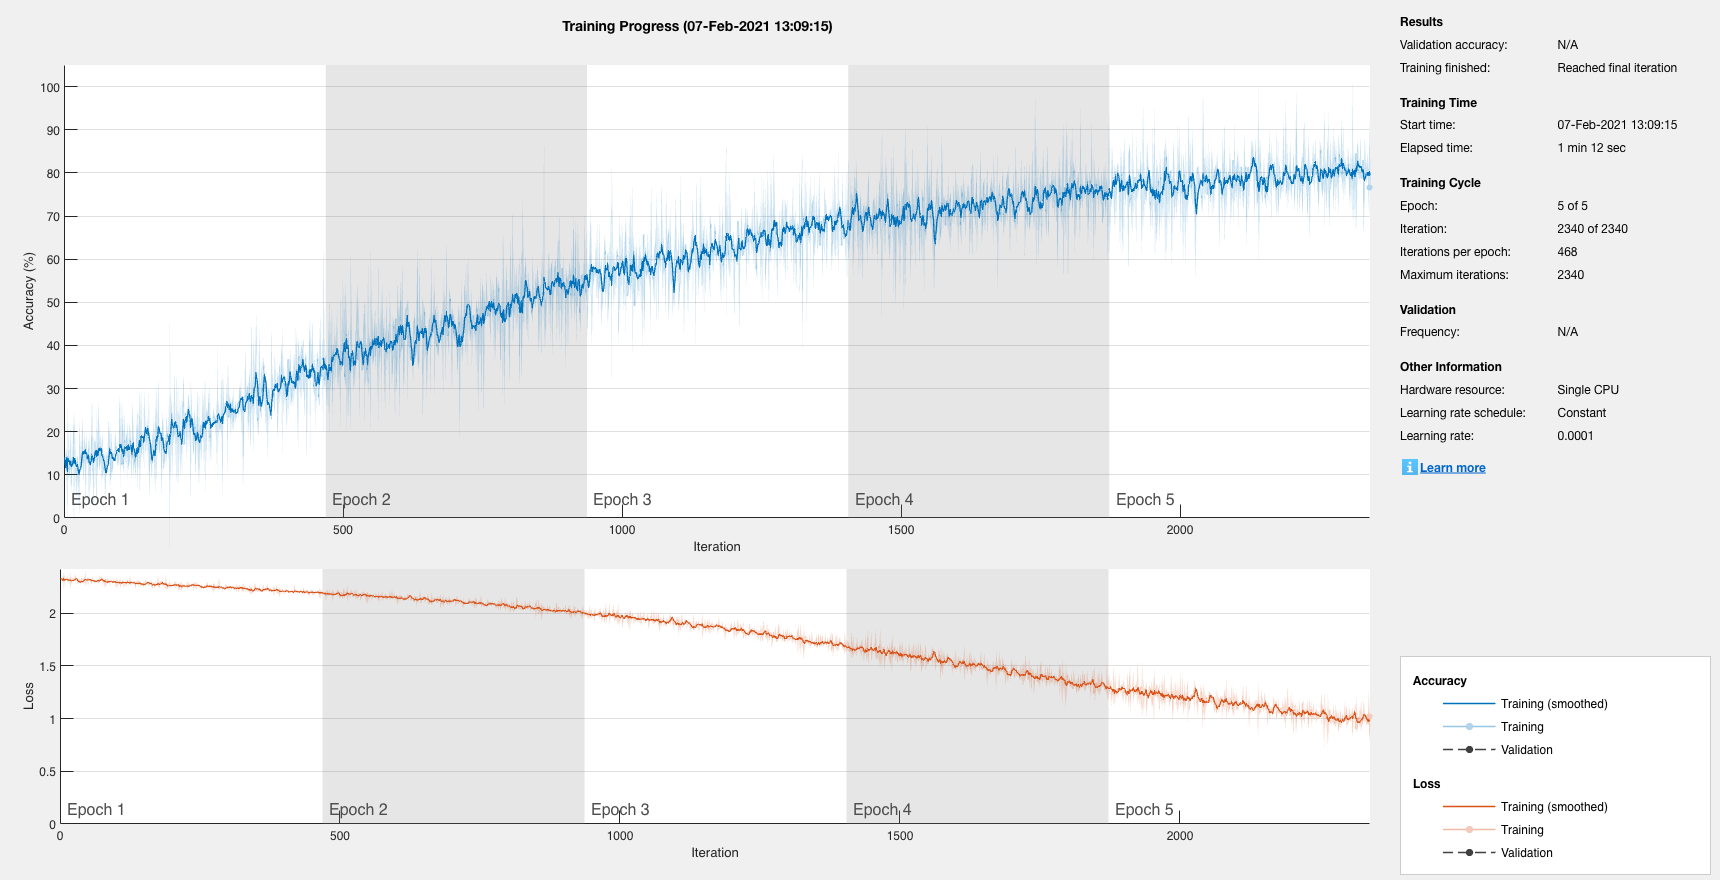

layers = [
imageInputLayer([d1, d2, 1])
convolution2dLayer(5,20)
reluLayer
maxPooling2dLayer(2,'Stride',2)
fullyConnectedLayer(10)
softmaxLayer
classificationLayer];

options = trainingOptions('sgdm', ...
'MaxEpochs',5,...
'InitialLearnRate',1e-4, ...
'Verbose',false, ...
'Plots','training-progress');

net = trainNetwork(Xtrain,labels_train,layers,options);

Label_test_predicted = classify(net, Xtest);

Unrecognized function or variable 'net'.

accuracy = sum(Label_test_predicted == labels_test)/numel(labels_test)